clear; 
close all;
clc;

Easy.jpeg

a) Count the total number of blocks 

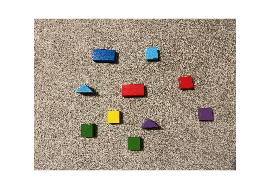

% read in image
easy = imread("easy.jpg");
imshow(easy)

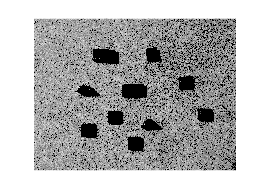

% convert image to grayscale 
easy_red = easy(:, :, 1);
easy_green = easy(:, :, 2);
easy_blue = easy(:, :, 3);

mask = easy_blue < 80;
easy(repmat(mask, [1,1,3])) = 0;

mask = easy_green < 80;
easy(repmat(mask, [1,1,3])) = 0;

mask = easy_red < 110;
easy(repmat(mask, [1,1,3])) = 0;

easy_gray = rgb2gray(easy);
imshow(easy_gray)

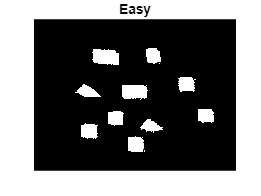

% preprocess image 
BW = imcomplement(easy_gray);
BW1 = imbinarize(BW);
BW2 = imfill(BW1,'holes');
BW3 = bwareaopen(BW2,4000);
imshow(BW3)
title('Easy')

% count number of shapes 
blocks = bwconncomp(BW3);
disp('The total number of blocks is  :');

The total number of blocks is  :


disp(blocks.NumObjects);

    10



b) Count the number of blocks of each colour 

%segment image by colour in lab colour space 
img = imread('easy.jpg');
lab_img = rgb2lab(img);
ab = lab_img(:,:,2:3);
ab = im2single(ab);
L = imsegkmeans(ab, 7,NumAttempts=7);

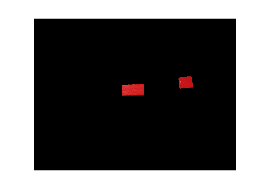

% red shapes 
mask2 = L == 2;
cluster2 = img.*uint8(mask2);
imshow(cluster2)


% preprocess image 
red = preProcessImage(cluster2);

% count number of shapes 
rblocks = bwconncomp(red);
disp('The total number of red blocks is  :')

The total number of red blocks is  :


disp(rblocks.NumObjects);

     2



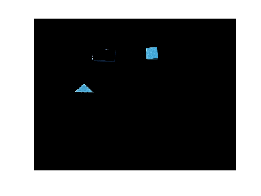

% light blue shapes 
mask3 = L == 3;
cluster3 = img.*uint8(mask3);
imshow(cluster3)

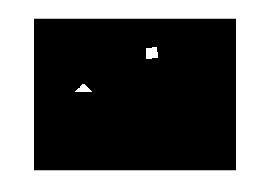


% preprocess image 
lblue = preProcessImage(cluster3);
imshow(lblue)


% count number of shapes 
lbblocks = bwconncomp(lblue);
disp('The total number of light bllue blocks is  :')

The total number of light bllue blocks is  :


disp(lbblocks.NumObjects);

     2



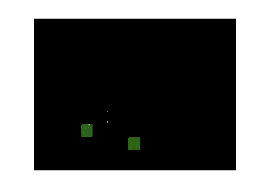

% green shapes
mask4 = L == 4;
cluster4 = img.*uint8(mask4);
imshow(cluster4)


% preprocess image 
green = preProcessImage(cluster4);

% count number of shapes 
gblocks = bwconncomp(green);
disp('The total number of green blocks is  :')

The total number of green blocks is  :


disp(gblocks.NumObjects);

     2



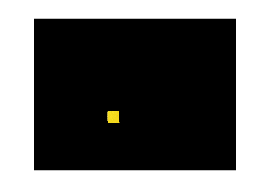

% yellow 
mask5 = L == 5;
cluster5 = img.*uint8(mask5);
imshow(cluster5)


% preprocess image 
yellow = preProcessImage(cluster5);

% count number of shapes 
yblocks = bwconncomp(yellow);
disp('The total number of yellow blocks is  :')

The total number of yellow blocks is  :


disp(yblocks.NumObjects);

     1



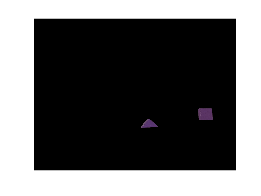

% purple
mask6 = L == 6;
cluster6 = img.*uint8(mask6);
imshow(cluster6)


% preprocess image 
purple = preProcessImage(cluster6);

% count number of shapes 
pblocks = bwconncomp(purple);
disp('The total number of purple blocks is  :')

The total number of purple blocks is  :


disp(pblocks.NumObjects);

     2



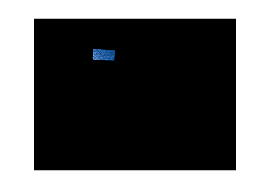

% dark blue 
mask7 = L == 7;
cluster7 = img.*uint8(mask7);
imshow(cluster7)


% preprocess image 
dblue = preProcessImage(cluster7);

% count number of shapes 
dbblocks = bwconncomp(dblue);
disp('The total number of dark blue blocks is  :')

The total number of dark blue blocks is  :


disp(dbblocks.NumObjects);

     1



c) Count number of blocks of each shape

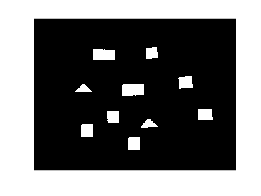

%fuse all coloured shapes into one image 
C = imfuse(yellow,red);
C = imfuse(C,lblue);
C = imfuse(C,dblue);
C = imfuse(C,purple);
C = imfuse(C,green);

% preprocess image 
BW3 = preProcessImage(C);

imshow(BW3)

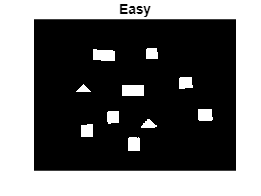

BW = BW3;
imshow(BW);
title('Easy')

shapeStruct = classifyBlocks(BW);
disp('The total number of blocks of each shape is   :')

The total number of blocks of each shape is   :


disp(shapeStruct);

    Rectangle: 2
       Square: 6
     Triangle: 2



d) Number of blocks of each shape of the same colour 

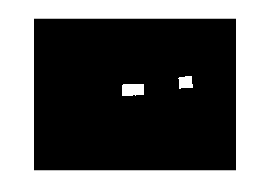

% red 
BW = red;
imshow(BW);

shapeStruct = classifyBlocks(BW);
disp('The total number of blocks of each shape that are red are   :')

The total number of blocks of each shape that are red are   :


disp(shapeStruct);

    Rectangle: 1
       Square: 1



% light blue
BW = lblue;
imshow(BW);

shapeStruct = classifyBlocks(BW);
disp('The total number of blocks of each shape that are light blue are   :')

The total number of blocks of each shape that are light blue are   :


disp(shapeStruct);

      Square: 1
    Triangle: 1



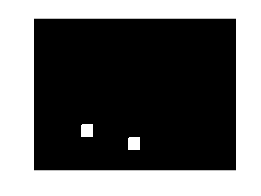

% green 
BW = green;
imshow(BW);

shapeStruct = classifyBlocks(BW);
disp('The total number of blocks of each shape that are green are   :')

The total number of blocks of each shape that are green are   :


disp(shapeStruct);

    Square: 2



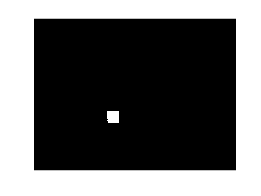

% yellow
BW = yellow;
imshow(BW);

shapeStruct = classifyBlocks(BW);
disp('The total number of blocks of each shape that are yellow are   :')

The total number of blocks of each shape that are yellow are   :


disp(shapeStruct);

    Square: 1



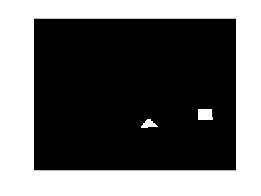

% purple
BW = purple;
imshow(BW);

shapeStruct = classifyBlocks(BW);
disp('The total number of blocks of each shape that are purple are   :')

The total number of blocks of each shape that are purple are   :


disp(shapeStruct);

      Square: 1
    Triangle: 1



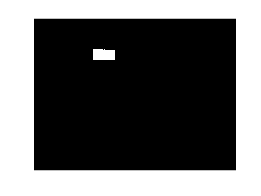

% dark blue 
BW = dblue;
imshow(BW);

shapeStruct = classifyBlocks(BW);
disp('The total number of blocks of each shape that are dark blue are   :')

The total number of blocks of each shape that are dark blue are   :


disp(shapeStruct);

    Rectangle: 1



function new_img = preProcessImage(img)
    img_gray = rgb2gray(img);
    BW1 = imbinarize(img_gray);
    BW2 = imfill(BW1,'holes');
    new_img = bwareaopen(BW2,4000);
end
function shapeStruct = classifyBlocks(BW)
    shapes = {};
    % identifies boundary of each object (B = boundaries),(L = labels objects and holes),(N = number of objects), 
    [B,L,N] = bwboundaries(BW);

    % calculate properties of all shapes and store in an array 
    stats =  regionprops(L, 'Area', 'Perimeter');
    area = cat(1, stats.Area);
    perimeter = cat(1,stats.Perimeter);

    for k=1:N
        % calculate smallest bounding box of object 
        boundary = B{k};
        [rx,ry,boxArea] = minboundrect( boundary(:,2), boundary(:,1));
        width = sqrt( sum( (rx(2)-rx(1)).^2 + (ry(2)-ry(1)).^2));
        height = sqrt( sum( (rx(2)-rx(3)).^2+ (ry(2)-ry(3)).^2));
        aspectRatio = width/height;

        if aspectRatio > 1
           aspectRatio = height/width;  %make aspect ratio less than unity
        end
        
        p = perimeter(k);
        a = area(k);

        % check if circle
        if ((p.^2)./(4*pi*a)) < 1.1
            shapes{end+1} = 'Circle';
        elseif (area(k)/boxArea) < 0.6
            shapes{end+1} = 'Triangle';
        elseif aspectRatio > 0.80
            shapes{end+1} = 'Square';
        else
            shapes{end+1} = 'Rectangle';
        end 
    end 
    % display the number of blocks of each shape 
    [uniqueShapes, ~, idx] = unique(shapes);
    shapeCounts = histcounts(idx, 1:length(uniqueShapes)+1);
    shapeStruct = struct();
    for i = 1:length(uniqueShapes)
        shapeStruct.(uniqueShapes{i}) = shapeCounts(i);
    end
end